
T=readtable('T_revisada_BuenaCalidad.csv')

T = 149×2 table
          image           glaucoma
    __________________    ________

    {'image_0009.jpg'}       0    
    {'image_0032.jpg'}       1    
    {'image_0048.jpg'}       0    
    {'image_0069.jpg'}       0    
    {'image_0078.jpg'}       0    
    {'image_0086.jpg'}       1    
    {'image_0094.jpg'}       0    
    {'image_0098.jpg'}       0    
    {'image_0128.jpg'}       1    
    {'image_0142.jpg'}       0    
    {'image_0175.jpg'}       0    
    {'image_0176.jpg'}       0    
    {'image_0206.jpg'}       0    
    {'image_0207.jpg'}       1    
    {'image_0208.jpg'}       0    
    {'image_0235.jpg'}       0    


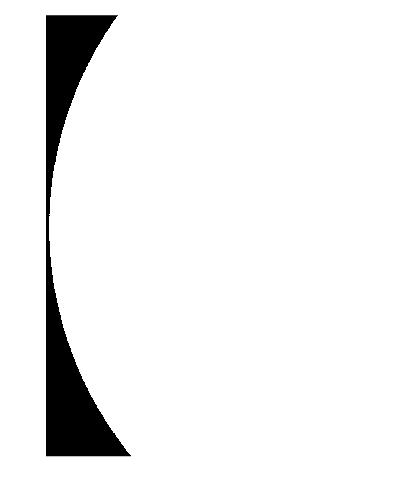

I_origen = imread(T.image{18});
I_gray=rgb2gray(I_origen);
I_thresholded=imbinarize(I_gray,0.1);
imshow(I_thresholded)


se = strel('disk', 40);
I_sinpunto=imopen(I_thresholded,se)

I_sinpunto = 1292×945 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

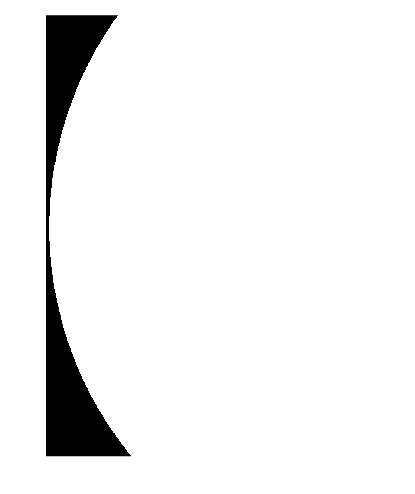

imshow(I_sinpunto)

I_double=im2double(I_origen)

I_double = I_double(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

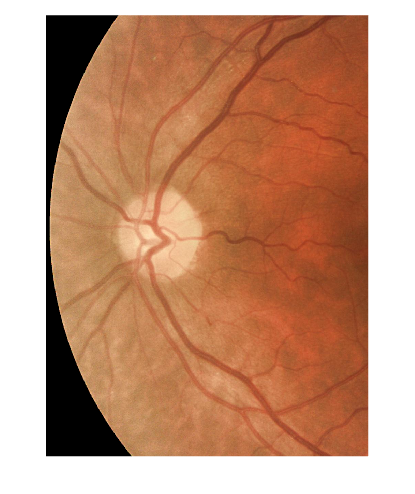


I_double(:,:,1)=I_double(:,:,1).*I_sinpunto;
I_double(:,:,2)=I_double(:,:,2).*I_sinpunto;
I_double(:,:,3)=I_double(:,:,3).*I_sinpunto;
imshow(I_double)


se=strel('disk', 90);
I_encogido=imerode(I_sinpunto,se)

I_encogido = 1292×945 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

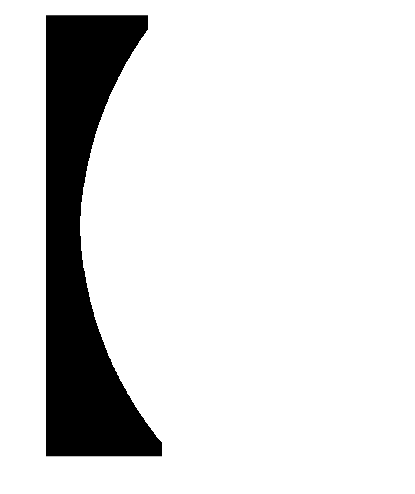

imshow(I_encogido)

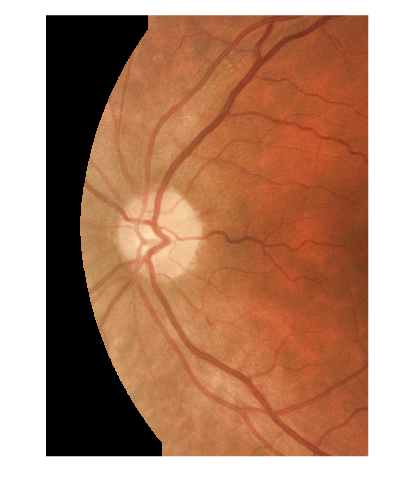

I_double(:,:,1)=I_double(:,:,1).*I_encogido;
I_double(:,:,2)=I_double(:,:,2).*I_encogido;
I_double(:,:,3)=I_double(:,:,3).*I_encogido;
imshow(I_double)

I_gray_2=rgb2gray(I_double);

I=adapthisteq(I_gray_2)

I =     0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139
    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0.0139    0

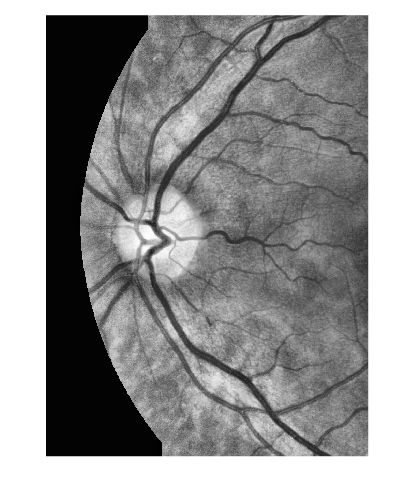

imshow(I)

figure; 
T_ROI=readtable('ROI\ROI_CalidadRevisada.csv')

T_ROI = 149×2 table
          image           glaucoma
    __________________    ________

    {'image_0009.jpg'}       0    
    {'image_0032.jpg'}       1    
    {'image_0048.jpg'}       0    
    {'image_0069.jpg'}       0    
    {'image_0078.jpg'}       0    
    {'image_0086.jpg'}       1    
    {'image_0094.jpg'}       0    
    {'image_0098.jpg'}       0    
    {'image_0128.jpg'}       1    
    {'image_0142.jpg'}       0    
    {'image_0175.jpg'}       0    
    {'image_0176.jpg'}       0    
    {'image_0206.jpg'}       0    
    {'image_0207.jpg'}       1    
    {'image_0208.jpg'}       0    
    {'image_0235.jpg'}       0    


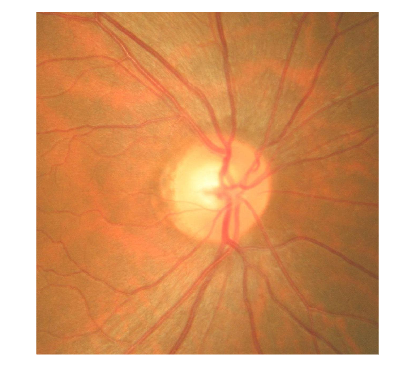

    ROI_origen= imread(T_ROI.image{1});
    imshow(ROI_origen)

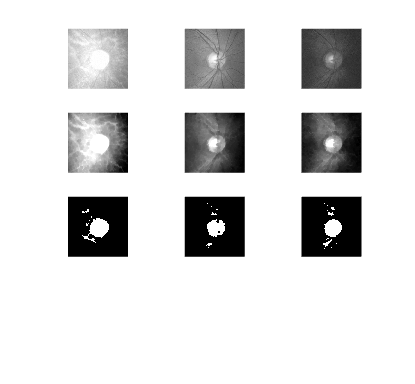

    canal_rojo= ROI_origen(:,:,1);
    canal_verde= ROI_origen(:,:,2);
    canal_azul= ROI_origen(:,:,3);

    subplot(4, 3, 1); title('ROI_Canal Rojo'); imshow(canal_rojo)
    subplot(4, 3, 2); title('ROI_Canal Verde'); imshow(canal_verde)
    subplot(4, 3, 3); title('ROI_Canal Azul'); imshow(canal_azul)
    
    % se = strel('disk', 300); 
    % background_rojo = imopen(canal_rojo, se);
    % background_verde = imopen(canal_verde, se);
    % background_azul = imopen(canal_azul, se);
    % 
    % corrected_image_rojo = imsubtract(canal_rojo, background_rojo);
    % corrected_image_verde = imsubtract(canal_verde, background_verde);
    % corrected_image_azul = imsubtract(canal_azul, background_azul);
    % fixed_dc_level = 100; 
    % I_iluminado_rojo = corrected_image_rojo + fixed_dc_level;
    % I_iluminado_verde = corrected_image_verde + fixed_dc_level;
    % I_iluminado_azul= corrected_image_azul + fixed_dc_level;
    % 
    % subplot(4, 3, 4); title('ROI_Canal Rojo'); imshow(I_iluminado_rojo)
    % subplot(4, 3, 5); title('ROI_Canal Verde'); imshow(I_iluminado_verde)
    % subplot(4, 3, 6); title('ROI_Canal Azul'); imshow(I_iluminado_azul)
    
    se = strel('disk', 20);
    I_vessels_rojo = imclose(canal_rojo, se);
    I_vessels_verde = imclose(canal_verde, se);
    I_vessels_azul = imclose(canal_azul, se);

    I_sinvenas_rojo=imadjust(I_vessels_rojo); 
    I_sinvenas_verde=imadjust(I_vessels_verde);
    I_sinvenas_azul=imadjust(I_vessels_azul);

    subplot(4, 3, 4); title('ROI_Canal Rojo'); imshow(I_sinvenas_rojo)
    subplot(4, 3, 5); title('ROI_Canal Verde'); imshow(I_sinvenas_verde)
    subplot(4, 3, 6); title('ROI_Canal Azul'); imshow(I_sinvenas_azul)

    sorted_values_rojo = sort(I_sinvenas_rojo(:), 'descend');
    sorted_values_verde = sort(I_sinvenas_verde(:), 'descend');
    sorted_values_azul = sort(I_sinvenas_azul(:), 'descend');

    threshold_index_disc_rojo = round(0.01 * numel(sorted_values_rojo));
    threshold_value_disc_rojo = sorted_values_rojo(threshold_index_disc_rojo);

    threshold_index_disc_verde = round(0.07 * numel(sorted_values_verde));
    threshold_value_disc_verde = sorted_values_verde(threshold_index_disc_verde);

    threshold_index_disc_azul = round(0.08 * numel(sorted_values_azul));
    threshold_value_disc_azul = sorted_values_azul(threshold_index_disc_azul);
    
    % Aplicar umbral para seleccionar el % de los píxeles de máxima calidad
    I_thresholded_disc_rojo = I_sinvenas_rojo >= threshold_value_disc_rojo;
    I_thresholded_disc_verde = I_sinvenas_verde >= threshold_value_disc_verde;
    I_thresholded_disc_azul = I_sinvenas_azul >= threshold_value_disc_azul;

    subplot(4, 3, 7); title('ROI_Canal Rojo'); imshow(I_thresholded_disc_rojo)
    subplot(4, 3, 8); title('ROI_Canal Verde'); imshow(I_thresholded_disc_verde)
    subplot(4, 3, 9); title('ROI_Canal Azul'); imshow(I_thresholded_disc_azul)

    figure; 
    Disco_segmentado=  I_thresholded_disc_rojo & I_thresholded_disc_verde & I_thresholded_disc_azul;
   
    Disco_segmentado_relleno=imfill(Disco_segmentado,'holes')

Disco_segmentado_relleno = 1289×1290 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

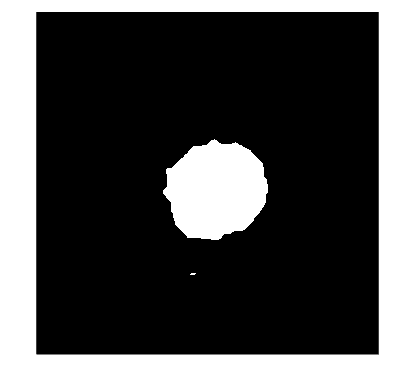

    se = strel('disk', 50);
    Disco_segmentado_cerrado=imclose(Disco_segmentado_relleno,se);

    figure;
    imshow(Disco_segmentado_cerrado);

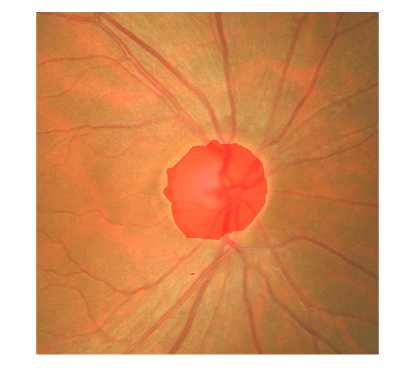


    figure; 
    title('ROI Combinada (AND)');
    imshow(ROI_origen);
    hold on;
    
    % Encontrar contornos de la imagen combinada
    [B, L] = bwboundaries(Disco_segmentado_cerrado, 'noholes');
    
    % Dibujar cada contorno encontrado
    for k = 1:length(B)
        boundary = B{k};
        fill(boundary(:,2), boundary(:,1), 'r', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    end
    hold off;